## Set up

clc
clear
clf
rng(16);

Preprocessing

SmarketD = readtable("Data\SmarketShuffle.csv");
SmarketD.Direction = categorical(SmarketD.Direction);
summary(SmarketD);

Variables:

    Var1: 1250×1 double

        Values:

            Min            1  
            Median     625.5  
            Max         1250  

    Year: 1250×1 double

        Values:

            Min         2001  
            Median      2003  
            Max         2005  

    Lag4: 1250×1 double

        Values:

            Min        -4.922 
            Median     0.0385 
            Max         5.733 

    Lag3: 1250×1 double

        Values:

            Min        -4.922 
            Median     0.0385 
            Max         5.733 

    Lag1: 1250×1 double

        Values:

            Min        -4.922 
            Median      0.039 
            Max         5.733 

    Lag2: 1250×1 double

        Values:

            Min        -4.922 
            Median      0.039 
            Max         5.733 

    Lag5: 1250×1 double

        Values:

           

Smarket = normalize(SmarketD(:,3:end-1));
Smarket.Direction = SmarketD.Direction;

% corrplot(Smarket(:,1:end-1));

## LDA

train = (SmarketD.Year < 2005);
Smarket2005 = Smarket(~train,:);
Direction2005 = SmarketD.Direction(~train,:);
ldafit = fitcdiscr(Smarket(train, 1:end-2), Smarket(train, end));
Direction = SmarketD.Direction;
num_components = 2; % Number of components in the reduced space
[eigenvectors, eigenvalues] = eig(ldafit.BetweenSigma, ldafit.Sigma);
lambda = diag(eigenvalues);
[lambda, sorted_indices] = sort(lambda, 'descend');
projection_matrix = eigenvectors(:, sorted_indices(1:num_components));

Smarket_reduced = table2array(Smarket(:,1:end-2)) * projection_matrix;
Smarket2005_reduced = Smarket_reduced(~train,:);

## K fold CV

% K = 10;
% N_size = size(Smarket(:,1));
% N = N_size(1);
% rand_N = randsample(1:N,N);
% sets = reshape(rand_N, K, []);
% 
% 
% for j = 1:K
%     val = sets(j,:);
%     trn = setdiff(rand_N,val);
%     
%     Smarket_r.data = Smarket_reduced(trn);
%     
%     num_neighbours = 5;
%     kNN_model_LDA = fitcknn(Smarket_r.data,Smarket.Direction(trn), 'NumNeighbors', num_neighbours, 'Standardize', 1);
%     
% end

k_values = 1:100;
cv_accuracies = zeros(1,length(k_values));
k_fold = 10;
cv = cvpartition(length(Smarket.Direction), 'KFold', k_fold);

for i = 1:length(k_values)
    k = k_values(i);
    accuracies = zeros(1, k_fold);
    
    for fold = 1:k_fold
        trn = training(cv, fold);
        tst = test(cv, fold);
        
        X_train = Smarket_reduced(trn, :);
        y_train = Smarket.Direction(trn);
        X_test = Smarket_reduced(tst, :);
        y_test = Smarket.Direction(tst);
        
        % Train kNN for current k
        kNN_model = fitcknn(X_train, y_train, 'NumNeighbors', k);
        
        y_pred = predict(kNN_model, X_test);
        
        accuracy = sum(y_pred == y_test) / length(y_test);
        accuracies(fold) = accuracy;
        
    end
    
    cv_accuracies(i) = mean(accuracies);
end
[M, I] = max(cv_accuracies);
best_k = k_values(I);

disp(['Best k: ', num2str(best_k)]);

Best k: 73


disp(['Cross validation accuracy with best k: ', num2str(M)]);

Cross validation accuracy with best k: 0.5264


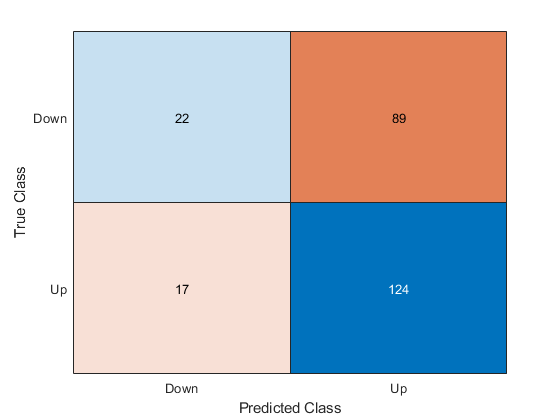


final_kNN_model = fitcknn(Smarket_reduced,Smarket.Direction, 'NumNeighbors', best_k);
% plot(1:100, correction_rate)
% title('kNN correction rate');
% xlabel('Correction rate');
% ylabel('Number of neighbours');

y_pred = predict(final_kNN_model, Smarket2005_reduced);
C = confusionmat(Direction2005, y_pred);
confusionchart(Direction2005, y_pred);

disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

    22    89
    17   124



correction_rate = sum(diag(C))/sum(C,"all");

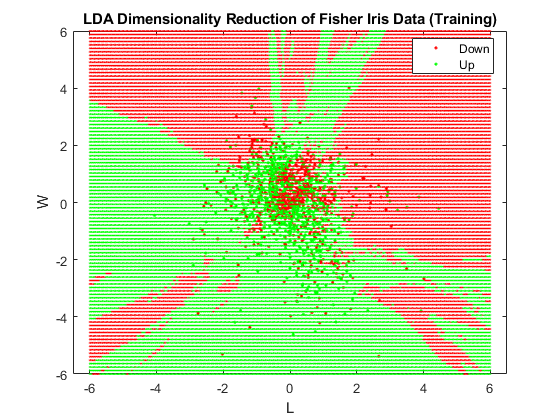

gscatter(Smarket_reduced(:, 1), Smarket_reduced(:, 2), Smarket.Direction, 'rg');
title('LDA Dimensionality Reduction of Fisher Iris Data (Training)');
xlabel('LDA Component 1');
ylabel('LDA Component 2');

[L, W] = meshgrid(linspace(-6, 6, 500), linspace(-6,6,100)); ...
L = L(:);
W = W(:);
pred = final_kNN_model.predict([L W]);
hold on;
h = gscatter(L, W, pred, 'rg', '.', 1, 'off'); set(h, 'LineWidth', 2, 'MarkerSize', 2)
legend('Down', 'Up', '', '');
hold off; 



% kNN_reduced = fitcdiscr(Smarket_reduced(train, :), Direction(train));
% 
% gscatter(Smarket_reduced(train, 1), Smarket_reduced(train, 2), Direction(train), 'rb');
% title('LDA Dimensionality Reduction of Smarket (Training)');
% xlabel('LDA Component 1');
% ylabel('LDA Component 2');
% legend('Up', 'Down', 'Location', 'best');
% 
% % [L, W] = meshgrid(linspace(-5, 5, 500), linspace(-5,5,100)); ...
% % L = L(:);
% % W = W(:);
% % pred = lda_reduced.predict([L W]);
% % hold on;
% % h = gscatter(L, W, pred, 'rb', '.', 1, 'off'); set(h, 'LineWidth', 2, 'MarkerSize', 2)
% % hold off; 
% 
% y_pred = predict(lda_reduced, Smarket2005_reduced);
% C = confusionmat(Direction2005, y_pred);
% disp('Confusion Matrix:');
% disp(C);

#### Prior probabilities

array2table(ldafit.Prior, 'VariableNames', cellstr(ldafit.ClassNames))

ans = 1×2 table
     Down        Up   
    _______    _______

    0.49198    0.50802


Group means

% array2table(ldafit.Mu, 'VariableNames',cellstr(ldafit.ClassNames))

Predictions

[ldaPredClass, ldaPredPosterior] = predict(kNN_model_LDA,Smarket2005_reduced);

Unrecognized function or variable 'kNN_model_LDA'.

confusionchart(ldaPredClass, Direction2005)
mean(ldaPredClass == Direction2005)

50% threshold

sum(ldaPredPosterior(:,1) >= 0.5)
sum(ldaPredPosterior(:,1) < 0.5)
ldaPredPosterior(1:20,1).'
ldaPredClass(1:20,1).'

% 90 %
sum(ldaPredPosterior(:,1) >= 0.9)

